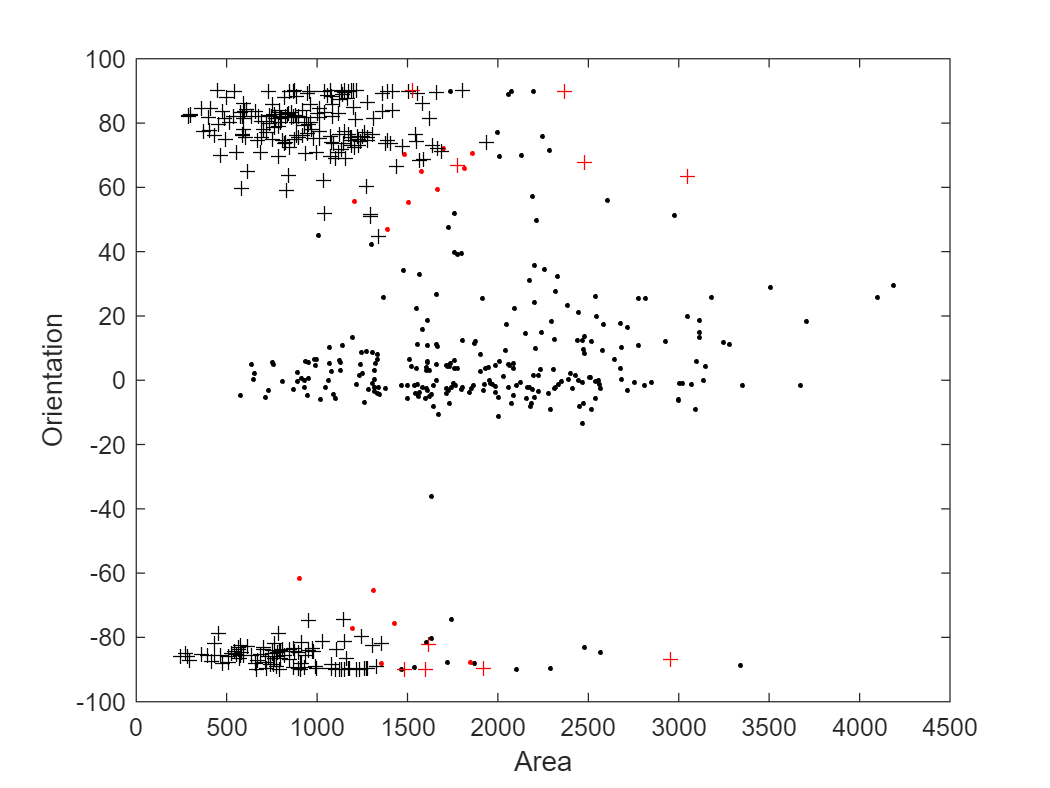

M = load('StudentData/FeaturesM');
T = load('StudentData/FeaturesT');

clear TrainingDataClass1
clear TrainingDataClass0

for sample = 1:300
TrainingDataClass0(:,sample) = ...
[M.Data(sample).Normal.Area,M.Data(sample).Normal.Orientation];
TrainingDataClass1(:,sample) = ...
[T.Data(sample).Normal.Area,T.Data(sample).Normal.Orientation];
end

ErrorsM=0;
ErrorsT=0;
figure;
for k = 301:600
F1 = M.Data(k).Normal.Area;
F2 = M.Data(k).Normal.Orientation;

if(ClassifierKNN([F1,F2],TrainingDataClass0,TrainingDataClass1) == 1) % Detected class "1"
ErrorsM = ErrorsM + 1;
plot(M.Data(k).Normal.Area,M.Data(k).Normal.Orientation,'.r'); hold on
else
plot(M.Data(k).Normal.Area,M.Data(k).Normal.Orientation,'.k'); hold on
end
F1 = T.Data(k).Normal.Area;
F2 = T.Data(k).Normal.Orientation;
if(ClassifierKNN([F1,F2],TrainingDataClass0,TrainingDataClass1) == 0) % Detected class "0
ErrorsT = ErrorsT + 1;
plot(T.Data(k).Normal.Area,T.Data(k).Normal.Orientation,'+r'); hold on
else
plot(T.Data(k).Normal.Area,T.Data(k).Normal.Orientation,'+k'); hold on
end
end
xlabel('Area');
ylabel('Orientation');

disp(ErrorsT)

    11



disp(ErrorsM)

    15



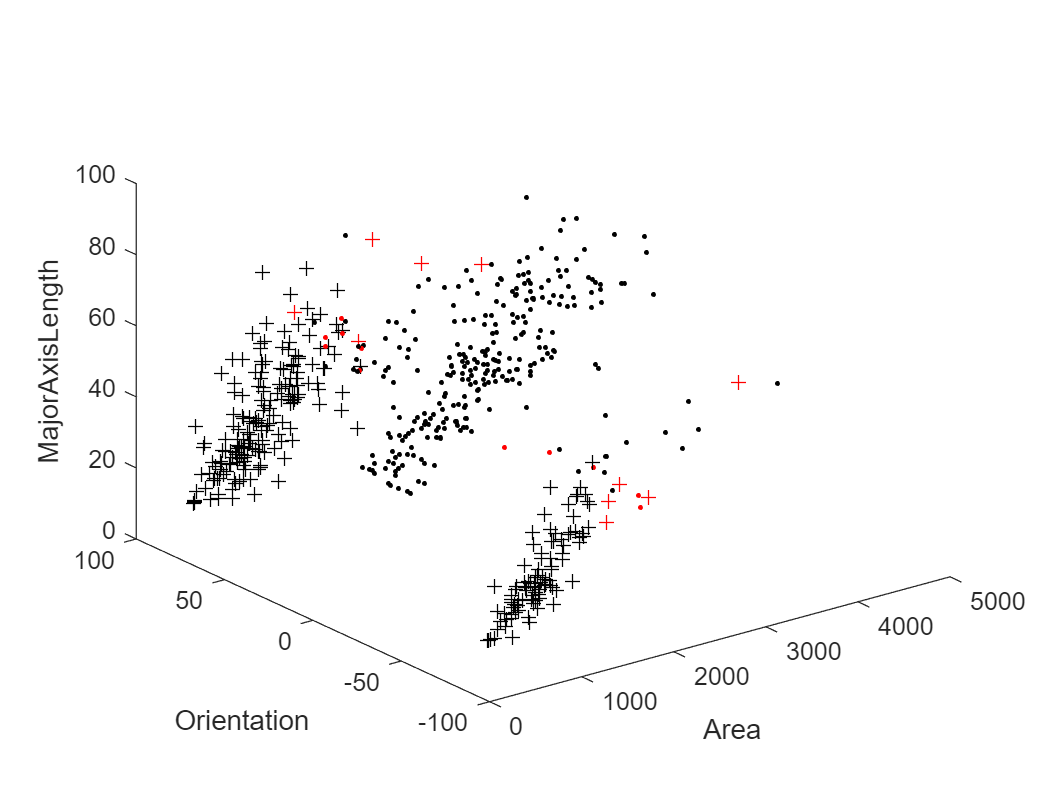


clear TrainingDataClass1
clear TrainingDataClass0


for sample = 1:300
TrainingDataClass0(:,sample) = ...
[M.Data(sample).Normal.Area,M.Data(sample).Normal.Orientation,...
M.Data(sample).Normal.MajorAxisLength,M.Data(sample).Normal.MinorAxisLength];
TrainingDataClass1(:,sample) = ...
[T.Data(sample).Normal.Area,T.Data(sample).Normal.Orientation,...
T.Data(sample).Normal.MajorAxisLength,T.Data(sample).Normal.MinorAxisLength];
end

ErrorsM=0;
ErrorsT=0;
figure;
for k = 301:600
F1 = M.Data(k).Normal.Area;
F2 = M.Data(k).Normal.Orientation;
F3 = M.Data(k).Normal.MajorAxisLength;
F4 = M.Data(k).Normal.MinorAxisLength;
if(ClassifierKNN([F1,F2,F3,F4],TrainingDataClass0,TrainingDataClass1) == 1) % Detected class "1"
ErrorsM = ErrorsM + 1;
plot3(M.Data(k).Normal.Area,M.Data(k).Normal.Orientation,M.Data(k).Normal.MinorAxisLength,'.r'); hold on
else
plot3(M.Data(k).Normal.Area,M.Data(k).Normal.Orientation,M.Data(k).Normal.MinorAxisLength,'.k'); hold on
end
F1 = T.Data(k).Normal.Area;
F2 = T.Data(k).Normal.Orientation;
F3 = T.Data(k).Normal.MajorAxisLength;
F4 = T.Data(k).Normal.MinorAxisLength;
if(ClassifierKNN([F1,F2,F3,F4],TrainingDataClass0,TrainingDataClass1) == 0) % Detected class "0
ErrorsT = ErrorsT + 1;
plot3(T.Data(k).Normal.Area,T.Data(k).Normal.Orientation,T.Data(k).Normal.MinorAxisLength,'+r'); hold on
else
plot3(T.Data(k).Normal.Area,T.Data(k).Normal.Orientation,T.Data(k).Normal.MinorAxisLength,'+k'); hold on
end
end
xlabel('Area');
ylabel('Orientation');
zlabel('MajorAxisLength')

disp(ErrorsT)

    11



disp(ErrorsM)

    11



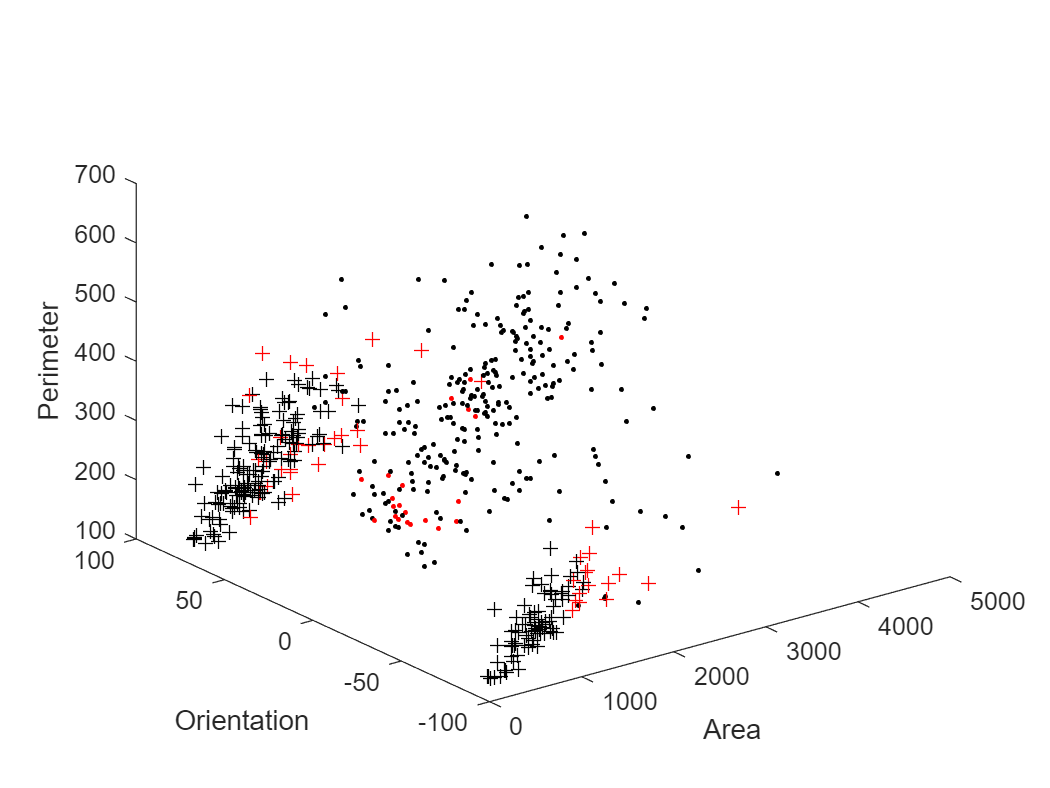

%norm dis
clear TrainingDataClass1
clear TrainingDataClass0


for sample = 1:300
TrainingDataClass0(:,sample) = ...
[M.Data(sample).Normal.Area,M.Data(sample).Normal.Orientation,...
M.Data(sample).Normal.ConvexArea,M.Data(sample).Normal.Perimeter];
TrainingDataClass1(:,sample) = ...
[T.Data(sample).Normal.Area,T.Data(sample).Normal.Orientation,...
T.Data(sample).Normal.ConvexArea,T.Data(sample).Normal.Perimeter];
end

ErrorsM=0;
ErrorsT=0;
figure;
for k = 301:600
F1 = M.Data(k).Normal.Area;
F2 = M.Data(k).Normal.Orientation;
F3 = M.Data(k).Normal.ConvexArea;
F4 = M.Data(k).Normal.Perimeter;
if(ClassifierKNN([F1,F2,F3,F4],TrainingDataClass0,TrainingDataClass1) == 1) % Detected class "1"
ErrorsM = ErrorsM + 1;
plot3(M.Data(k).Normal.Area,M.Data(k).Normal.Orientation,M.Data(k).Normal.Perimeter,'.r'); hold on
else
plot3(M.Data(k).Normal.Area,M.Data(k).Normal.Orientation,M.Data(k).Normal.Perimeter,'.k'); hold on
end
F1 = T.Data(k).Normal.Area;
F2 = T.Data(k).Normal.Orientation;
F3 = T.Data(k).Normal.ConvexArea;
F4 = T.Data(k).Normal.Perimeter;
if(ClassifierKNN([F1,F2,F3,F4],TrainingDataClass0,TrainingDataClass1) == 0) % Detected class "0
ErrorsT = ErrorsT + 1;
plot3(T.Data(k).Normal.Area,T.Data(k).Normal.Orientation,T.Data(k).Normal.Perimeter,'+r'); hold on
else
plot3(T.Data(k).Normal.Area,T.Data(k).Normal.Orientation,T.Data(k).Normal.Perimeter,'+k'); hold on
end
end
xlabel('Area');
ylabel('Orientation');
zlabel('Perimeter')

disp(ErrorsT)

    47



disp(ErrorsM)

    22



clear TrainingDataClass1
clear TrainingDataClass0


for sample = 1:300
TrainingDataClass0(:,sample) = ...
[M.Data(sample).Normal.Area,M.Data(sample).Normal.Orientation,...
M.Data(sample).Normal.ConvexArea,M.Data(sample).Normal.Perimeter];
TrainingDataClass1(:,sample) = ...
[T.Data(sample).Normal.Area,T.Data(sample).Normal.Orientation,...
T.Data(sample).Normal.ConvexArea,T.Data(sample).Normal.Perimeter];
end

Means = abs(mean([TrainingDataClass0,TrainingDataClass1]'));

TrainingDataClass0 = TrainingDataClass0./Means';
TrainingDataClass1 = TrainingDataClass1./Means';


ErrorsM=0;
ErrorsT=0;
% figure;
for k = 301:600
F1 = M.Data(k).Normal.Area/Means(1);
F2 = M.Data(k).Normal.Orientation/Means(2);
F3 = M.Data(k).Normal.ConvexArea/Means(3);
F4 = M.Data(k).Normal.Perimeter/Means(4);
if(ClassifierKNN([F1,F2,F3,F4],TrainingDataClass0,TrainingDataClass1) == 1) % Detected class "1"
ErrorsM = ErrorsM + 1;
% plot3(M.Data(k).Normal.Area/Means(1),M.Data(k).Normal.Orientation,M.Data(k).Normal.Perimeter,'.r'); hold on
else
% plot3(M.Data(k).Normal.Area,M.Data(k).Normal.Orientation,M.Data(k).Normal.Perimeter,'.k'); hold on
end
F1 = T.Data(k).Normal.Area/Means(1);
F2 = T.Data(k).Normal.Orientation/Means(2);
F3 = T.Data(k).Normal.ConvexArea/Means(3);
F4 = T.Data(k).Normal.Perimeter/Means(4);
if(ClassifierKNN([F1,F2,F3,F4],TrainingDataClass0,TrainingDataClass1) == 0) % Detected class "0
ErrorsT = ErrorsT + 1;
% plot3(T.Data(k).Normal.Area,T.Data(k).Normal.Orientation,T.Data(k).Normal.Perimeter,'+r'); hold on
else
% plot3(T.Data(k).Normal.Area,T.Data(k).Normal.Orientation,T.Data(k).Normal.Perimeter,'+k'); hold on
end
end
% xlabel('Area');
% ylabel('Orientation');
% zlabel('Perimeter')
disp(ErrorsT)

     7



disp(ErrorsM)

    19



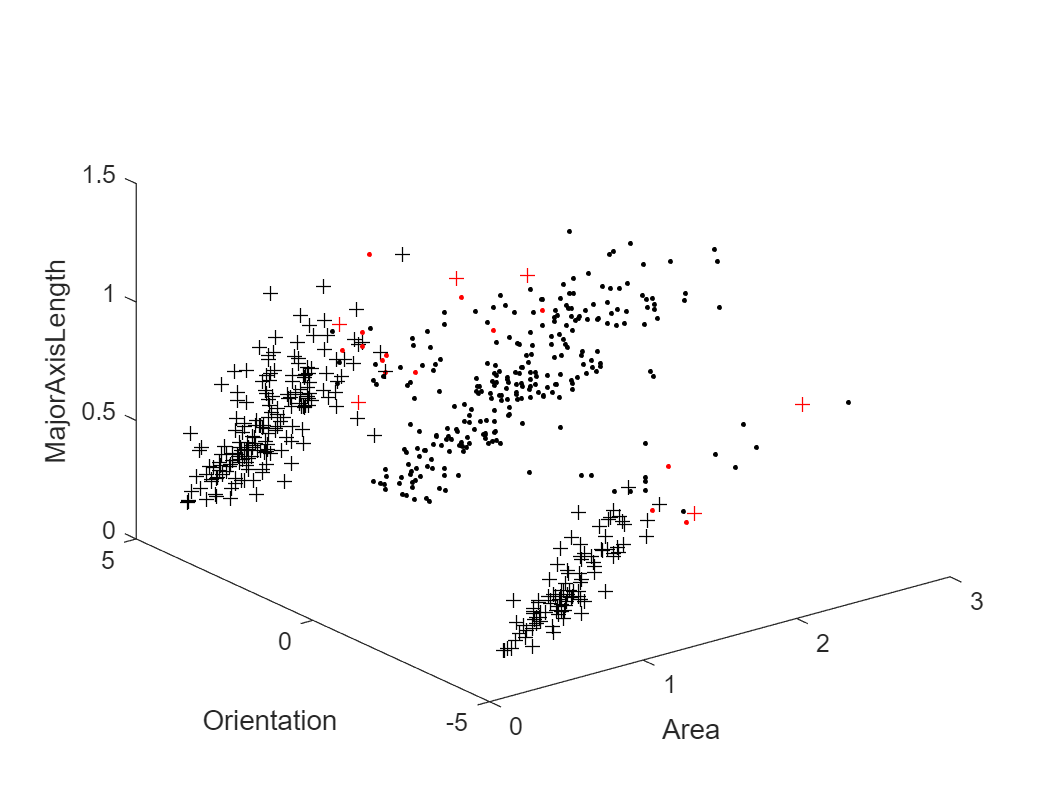

clear TrainingDataClass1
clear TrainingDataClass0


for sample = 1:300
TrainingDataClass0(:,sample) = ...
[M.Data(sample).Normal.Area,M.Data(sample).Normal.Orientation,...
M.Data(sample).Normal.MajorAxisLength,M.Data(sample).Normal.MinorAxisLength];
TrainingDataClass1(:,sample) = ...
[T.Data(sample).Normal.Area,T.Data(sample).Normal.Orientation,...
T.Data(sample).Normal.MajorAxisLength,T.Data(sample).Normal.MinorAxisLength];
end

% Finding of the means for the whole dataset
Means = abs(mean([TrainingDataClass0,TrainingDataClass1]'));
% Dividing the data:
TrainingDataClass0 = TrainingDataClass0./Means';
TrainingDataClass1 = TrainingDataClass1./Means';

ErrorsM=0;
ErrorsT=0;
figure;
for k = 301:600
F1 = M.Data(k).Normal.Area/Means(1);
F2 = M.Data(k).Normal.Orientation/Means(2);
F3 = M.Data(k).Normal.MajorAxisLength/Means(3);
F4 = M.Data(k).Normal.MinorAxisLength/Means(4);
if(ClassifierKNN([F1,F2,F3,F4],TrainingDataClass0,TrainingDataClass1) == 1) % Detected class "1"
ErrorsM = ErrorsM + 1;
plot3(M.Data(k).Normal.Area/Means(1),M.Data(k).Normal.Orientation/Means(2),M.Data(k).Normal.MinorAxisLength/Means(3),'.r'); hold on
else
plot3(M.Data(k).Normal.Area/Means(1),M.Data(k).Normal.Orientation/Means(2),M.Data(k).Normal.MinorAxisLength/Means(3),'.k'); hold on
end
F1 = T.Data(k).Normal.Area/Means(1);
F2 = T.Data(k).Normal.Orientation/Means(2);
F3 = T.Data(k).Normal.MajorAxisLength/Means(3);
F4 = T.Data(k).Normal.MinorAxisLength/Means(4);
if(ClassifierKNN([F1,F2,F3,F4],TrainingDataClass0,TrainingDataClass1) == 0) % Detected class "0
ErrorsT = ErrorsT + 1;
plot3(T.Data(k).Normal.Area/Means(1),T.Data(k).Normal.Orientation/Means(2),T.Data(k).Normal.MinorAxisLength/Means(3),'+r'); hold on
else
plot3(T.Data(k).Normal.Area/Means(1),T.Data(k).Normal.Orientation/Means(2),T.Data(k).Normal.MinorAxisLength/Means(3),'+k'); hold on
end
end
xlabel('Area');
ylabel('Orientation');
zlabel('MajorAxisLength')

disp(ErrorsT)

     6



disp(ErrorsM)

    14



function[Class] = ClassifierKNN(Features, TrainingDataClass0,TrainingDataClass1)
distancesC1 = dist(Features,TrainingDataClass0);
distancesC2 = dist(Features,TrainingDataClass1);
if(min(distancesC1) < min(distancesC2))
Class = 0;
else
Class = 1;
end
end